### Assignment 2.1

myfib(15)

ans = 610.0000

### Assignment 2.2

fib_ration(2)

ans = 1

fib_ration(10)

ans = 1.6176

fib_ration(100)

ans = 1.6180

fib_ration(1000)

ans = 1.6180

When n get large, the ratio  $\frac{F_n }{F_{n-1} }$ will approaching $\frac{1+\sqrt{5}}{2}$. 

### Assignment 2.3

disp(print_radius(3, 4, -11))

Radius of this circle is 6


### Assignment 2.4

find_integrate(1, 1)    % m == n

ans = 3.1416


find_integrate(10, 10)  % m == n

ans = 3.1416


find_integrate(50, 50)  % m == n

ans = 3.1416


find_integrate(1, 10)   % m != n

ans = -2.2204e-16


find_integrate(1, 50)   % m != n

ans = -4.2674e-16


find_integrate(1, 100)  % m != n

ans = 5.1001e-16

We can find that the solution of $\int_{-\pi }^{\pi } \sin \left(m\cdot x\right)\cdot \sin \left(n\cdot x\right)\mathrm{dx}$ is $\pi$ when $m$ is equal to $n$ or $0$ when $m$ is not equal to $n$. 

### Assignment 2.5

A = zeros(5, 5);
for i = 1:5
    for j = 1:5
        A(i, j) = xor(mod(i, 2), mod(j+1, 2));
    end
end
A

A =      1     0     1     0     1
     0     1     0     1     0
     1     0     1     0     1
     0     1     0     1     0
     1     0     1     0     1


### Assignment 2.6

> Begin and end values are included. 

check_square_numbers(900, 950)

ans = 30

### Assignment 2.7

geometric_progression(1, 0.5, 5)

ans = 1.9688

### Assignment 2.8

(2^56+5)-2^56

ans = 0

ans=0, which means 2^56 is the maxium of Integer in MATLAB. 

### Assignment 2.9

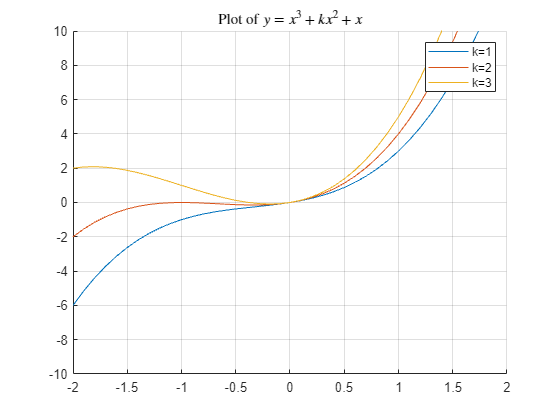

clc
clf
Tit =title('Plot of $y=x^3 + kx^2 + x $');
set(Tit,'Interpreter','latex');

x = -2:0.1:2;
ylim([-10 10]);
grid on;
hold on;
for k = 1:3
    y = x.^3+k*x.^2+x;
    plot(x, y);
    le{k} = ['k=', mat2str(k)];
end
legend(le)
hold off

### Assignment 2.10

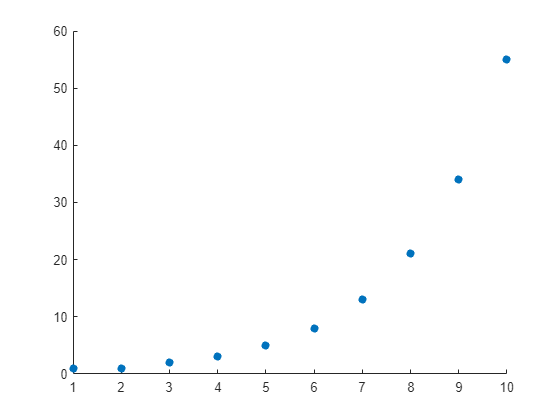

x = 1:10;
y = 1:10;
for n = 1:10
    y(n) = fibonacci(n);
end
scatter(x, y, 'filled')

### Function define

function fib = myfib(n)                         % 2.1
    g_ratio = (1 + sqrt(5))/2;
    fib = (g_ratio^n-(-g_ratio)^(-n))/sqrt(5);
end

function r = fib_ration(n)                      % 2.2
    r = fibonacci(n)/fibonacci(n-1);
end

function ret = print_radius(g, f, c)            % 2.3.1
    ret = sprintf('Radius of this circle is %d', find_radius(g, f, c));
end

function radius = find_radius(g, f, c)          % 2.3.2
    radius = sqrt(g^2+f^2-c);
end

function ret = find_integrate(m, n)             % 2.4
    ret = integral(@(x) sin(m.*x).*sin(n.*x), -pi, pi);
end

function ret = check_square_numbers(a, b)       % 2.6
    GLB = ceil(sqrt(a));
    if GLB^2 >= b
        ret = "There are no square numbers";
        return
    end
    ret = [];
    while GLB^2 <= b
        ret = [ret GLB];
        GLB = GLB + 1;
    end
end

function ret = geometric_progression(a, r, n)   %2.7
    ret = 0;
    for i = 0:n
        ret = ret + a * r ^i;
    end
end